# Chapter 3 Exercise Solutions

#### Exercise 3.1

Checking $B(k)$ condition


$$\begin{array}{llll}
  j &= 1: & b_1 + b_2 = \frac{1}{2} + \frac{1}{2} = 1, \\
  j &= 2: & b_1c_1 + b_2c_2 = \frac{1}{2} \left( \frac{1}{4} \right) + \frac{1}{2} \left( \frac{3}{4} \right) = \frac{1}{2}, \\
  j &= 3: & b_1c_1^2 + b_2c_2^2 = \frac{1}{2} \left( \frac{1}{16} \right) + \frac{1}{2} \left( \frac{9}{16} \right) = \frac{5}{16}
\end{array}$$


So $B(2)$ is satisfied. Checking $C(1)$


$$\begin{array}{llll}
  i &= 1: && LHS: a_{11} + a_{12} = \frac{1}{4} + 0 = \frac{1}{4}, \\
  &&& RHS: c_1 = \frac{1}{4}, \\
  i &= 2: && LHS: a_{21} + a_{22} = \frac{1}{2} + \frac{1}{4} = \frac{3}{4}, \\
  &&& RHS: c_2 = \frac{3}{4}.
\end{array}$$


So $C(1)$ is satisfied. Checking $D(1)$


$$\begin{array}{llll}
  j &= 1: && LHS: b_1a_{11} + b_2a_{21} = \frac{1}{2}\left( \frac{1}{4} \right) + \frac{1}{2} \left( \frac{1}{2} \right) = \frac{3}{8}, \\
  &&& RHS: b_1(1 - c_1) = \frac{1}{2}\left( 1 - \frac{1}{4} \right) = \frac{3}{8}, \\
  j &= 2: && LHS: b_1a_{12} + b_2a_{22} = \frac{1}{2} (0) + \frac{1}{2} \left( \frac{1}{4} \right) = \frac{1}{8}, \\
  &&& RHS: b_2 (1 - c_!) = \frac{1}{2} \left( 1 - \frac{3}{4} \right) = \frac{1}{8}.
\end{array}$$


Since $B(2)$, $C(1)$ and $D(1)$ are satisfied this is a second-order method.

#### Exercise 3.2

syms a11 a12 a21 a22 b1 b2 x

function P = legendre(n)

syms x
P = 0;
for i = 0 : n
    P = P + nchoosek(n, i) * nchoosek(n + i, i) * (x - 1)^i;
end

end

% Calculate c coefficients
P = legendre(2) - legendre(1);
c = solve(P)

$$c = \left(\begin{array}{c} \frac{1}{3}\\ 1 \end{array}\right)$$

c1 = c(1);
c2 = c(2);

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b1 * c1 + b2 * c2 == 1/2;
eq3 = a11 + a12 == c1;
eq4 = a21 + a22 == c2;
eq5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eq6 = a21 * c1 + a22 * c2 == 1/2 * c2^2;

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a11: 5/12
    a12: -1/12
    a21: 3/4
    a22: 1/4
     b1: 3/4
     b2: 1/4


So the third-order Radau IIA method is


$$  \begin{array}{c|cc}
    \frac{1}{3} & \frac{5}{12} & -\frac{1}{12} \\
    1 & \frac{3}{4} & \frac{1}{4} \\ 
    \hline
    & \frac{3}{4} & \frac{1}{4}
  \end{array}$$


#### Exercise 3.3

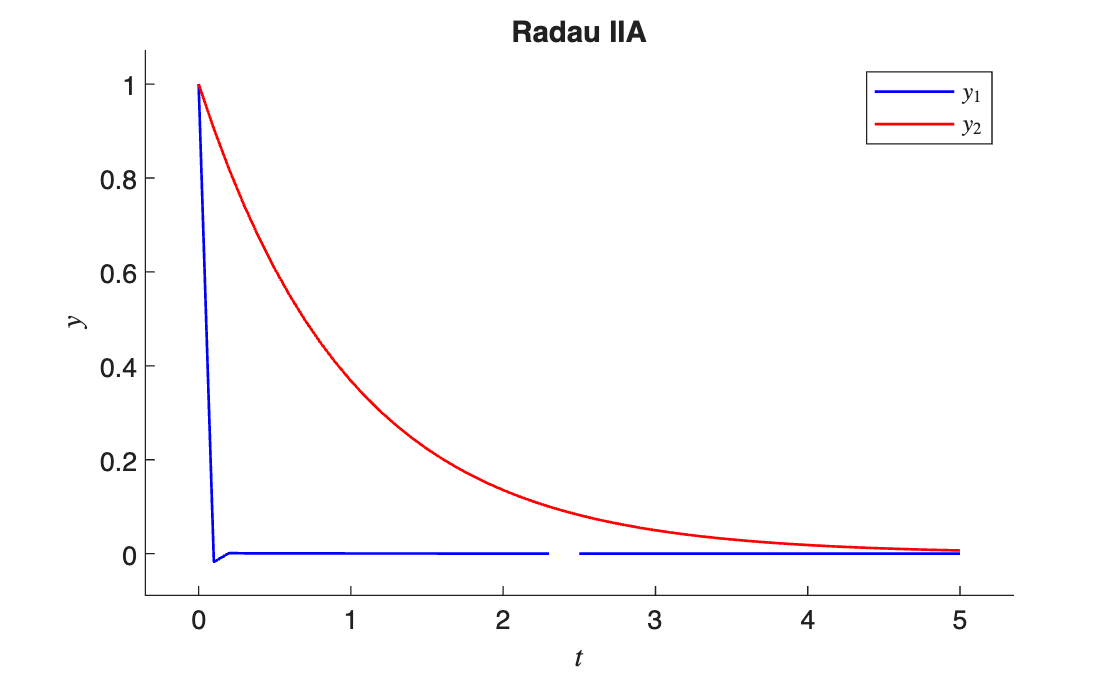

% Define Jacobian function
function J = jac(f, t, y)

N = length(y);
J = zeros(N, N);
epsilon = 1e-2;
for i = 1 : N
    y_plus_epsilon = y;
    y_plus_epsilon(i) = y_plus_epsilon(i) + epsilon;
    J(:, i) = (f(t, y_plus_epsilon) - f(t, y)) / epsilon;
end

end

% Define Radau IIA function
function [t, y] = radauIIA(f, tspan, y0, h)

N = length(y0);
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, N);
t(1) = tspan(1);
y(1,:) = y0;

A = [ 5/12, -1/12 ; 
      3/4, 1/4 ];
b = [ 3/4 ; 1/4 ];
c = [ 1/3 ; 1 ];
s = 2;

for n = 1 : nsteps

    z = zeros(N * s, 1);
    F = zeros(N * s, 1);
    J = jac(f, t(n), y(n,:));
    for k = 1 : 10
        F = [f(t(n) * c(1) * h, y(n,:) + z(1:N)') ;
             f(t(n) * c(2) * h, y(n,:) + z(N+1:end)')];
        g = z - h * kron(A, eye(N)) * F;
        delta_z = (eye(N * s) - h * kron(A, J)) \ -g;
        z = z + delta_z;
        if norm(delta_z) < 1e-6
            break
        end
    end

    y(n+1,:) = y(n,:) + (h * kron(b', eye(N)) * F)';
    t(n+1) = t(n) + h;
end

end

% Define ODE function
f = @(t, y) [ -1000 * y(1) + y(2) ; -y(2) ];

% Define IVP
tspan = [0, 5];
y0 = [1 , 1];
h = 0.1;

% Solve IVP
[t, y] = radauIIA(f, tspan, y0, h);

% Plot solution
clf
hold on
plot(t, y(:,1), "b", LineWidth=1)
plot(t, y(:,2), "r", LineWidth=1)
xlabel('$t$', Interpreter='latex')
ylabel('$y$', Interpreter='latex')
legend('$y_1$', '$y_2$', Interpreter='latex')
title('Radau IIA')
hold off
axis padded

(b)

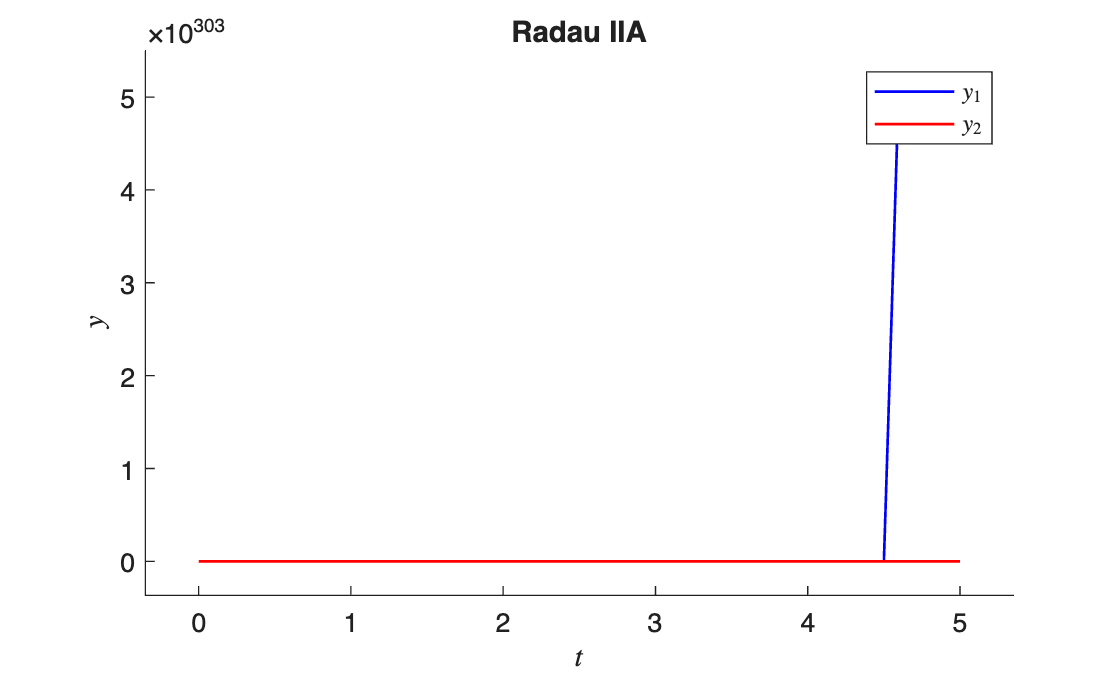

% Define RK4 function
function [t, y] = rk4(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, m);
t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/3 * h, y(n,:) + 1/3 * h * k1);
    k3 = f(t(n) + 1/2 * h, y(n,:) + h * (1/8 * k1 + 3/8 * k2));
    k4 = f(t(n) + h, y(n,:) + h * (1/2 * k1 - 3/2 * k2 + 2 * k3));
    y(n+1,:) = y(n,:) + h / 6 * (k1 + 4 * k3 + k4);
    t(n+1) = t(n) + h;
end

end

% Define ODE function
f = @(t, y) [ -1000 * y(1) + y(2) , -y(2) ];

% Solve IVP
[t, y] = rk4(f, tspan, y0, h);

% Plot solution
clf
hold on
plot(t, y(:,1), "b", LineWidth=1)
plot(t, y(:,2), "r", LineWidth=1)
xlabel('$t$', Interpreter='latex')
ylabel('$y$', Interpreter='latex')
legend('$y_1$', '$y_2$', Interpreter='latex')
title('Radau IIA')
hold off
axis padded

The RK4 method is unstable for this problem.

(c)

% Define RKF45 function
function [t, y] = rkf45(f, tspan, y0, atol, rtol)

m = length(y0);
t = zeros(100000, 1);
y = zeros(100000, m);
t(1) = tspan(1);
y(1,:) = y0;

h = 0.8 * rtol ^ (1/5);
n = 1;
while t(n) < tspan(2)

    k1 = f(t(n), y(n,:));
    k2 = f(t(n) + 1/4 * h, y(n,:) + 1/4 * h * k1);
    k3 = f(t(n) + 3/8 * h, y(n,:) + h * (3/32*k1 + 9/32 * k2));
    k4 = f(t(n) + 12/13 * h, y(n,:) + h * (1932/2197 * k1 - 7200/2197 * k2 + 7296/2197 * k3));
    k5 = f(t(n) + h, y(n,:) + h * (439/216 * k1 - 8 * k2 + 3680/513 * k3 - 845/4104 * k4));
    k6 = f(t(n) + 1/2 * h, y(n,:) + h * (-8/27 * k1 + 2 * k2 - 3544/2565 * k3 + 1859/4104 * k4 - 11/40 * k5));

    y5 = y(n,:) + h * (16/135 * k1 + 6656/12825 * k3 + 28561/56430 * k4 - 9/50 * k5 + 2/55 * k6);
    y4 = y(n,:) + h * (25/216 * k1 + 1408/2565 * k3 + 2197/4104 * k4 - 1/5 * k5);

    delta = norm(y5 - y4);
    tol = atol + rtol * min(abs(y5));
    if delta < tol
        y(n+1,:) = y5;
        t(n+1) = t(n) + h;
        n = n + 1;
    end

    r = max(0.1, 0.8 * (tol / delta) ^ (1/5));
    h = min(r * h, tspan(2) - t(n));
end

t(n+1:end) = [];
y(n+1:end,:) = [];

end


% Define ODE functions (Radau IIA method needs the function to output a 2x1
% vector)
f = @(t, y) [ -1000 * y(1) + y(2) , -y(2) ];
f2 = @(t, y) [ -1000 * y(1) + y(2) ; -y(2) ];

% Solve IVP using RKF45 and Radau IIA methods and record the time taken and
% compute the smallest step length used for RKF45

tic;
[t_rkf45, ~] = rkf45(f, tspan, y0, 1e-6, 1e-3);
rkf45time = toc;

tic;
[t_radauIIA, ~] = radauIIA(f2, tspan, y0, h);
radauIIAtime = toc;

fprintf("RKF45 time: %0.3f seconds", rkf45time)

RKF45 time: 0.030 seconds

fprintf("Radau IIA time: %0.3f seconds", radauIIAtime)

Radau IIA time: 0.012 seconds

fprintf("Smallest step length used by RKF45: %0.6f", min(t_rkf45(2:end) - t_rkf45(1:end-1)))

Smallest step length used by RKF45: 0.000427